clear all;
A = [0 1 0;
    0 0 1;
    -2 -3 -5];
B = [0;
    0;
    1];
C = [1 0 0];
D = 0;
sys = ss(A,B,C,D);

% ans!=0 이면 controllable, observable 하다
rank(ctrb(sys)) %controllability 판별

ans = 3

rank(obsv(sys)) %observability 판별

ans = 3

clearvars; %작업공간비우기
A = [2 0;
    -1 1];
B = [1;
    -1];
C = [1 1];
D = 0;
sys = ss(A,B,C,D);

rank(ctrb(sys)) %controllability 판별

ans = 1

rank(obsv(sys)) %observability 판별

ans = 1


% 2x2 matrix 이기 때문에 ans = 2가 나와야 하는데
% 1이 나온걸 보면 controllable, observable 하지 않다.

Full state feedback

% system declaration
clearvars;
A = [0 1 0;
    0 0 1;
    -2 -3 -5];
B = [0;
    0;
    1];
C = [1 0 0];
D = 0;

% control requirments
zeta = 0.8;
w_n = 6;

% charicteristic equation for the requirements
% mtarix를 보면 (A가 3x3) 3차식이지만 zeta wn 은 2차식에 쓴다.
% 3차식은 2차식 x 1차식 이므로 1차식의 pole은 적당히 큰 값(zeta*w_n)을 주고,
% 2차식은 zeta 와 wn으로 결정한다.
poly1 = [1 2*zeta*w_n w_n^2]

poly1 =     1.0000    9.6000   36.0000


poly2 = [1 zeta*w_n]

poly2 =     1.0000    4.8000


ploy = conv(poly1, poly2)

ploy =     1.0000   14.4000   82.0800  172.8000


root = roots(ploy)

root =   -4.8000 + 3.6000i
  -4.8000 - 3.6000i
  -4.8000 + 0.0000i



% ploe placement using Ackermann's folmula
K = place(A,B,root)

K =   170.8000   79.0800    9.4000



% Connect the compensator and simulate
% u(t) = -K*x(t)
% x'(t) = A*x(t) + B*u(t) = (A-B*K)*x(t) = A'*x(t)
sys_cl = ss(A-B*K,B,C,D);
t = 0:0.01:2

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


u = zeros(size(t))

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x0 = [0.01 0 0] % 초기값

x0 =     0.0100         0         0


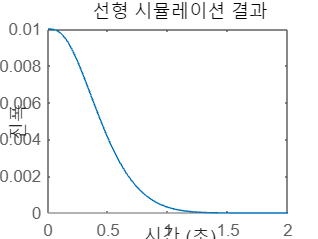

lsim(sys_cl, u, t, x0)

% 임의로 pole 선정
r1 = -10 + 10i;
r2 = -10 - 10i;
r3 = -50

r3 = -50

K = place(A,B,[r1 r2 r3])

K = 1.0e+03 *

    9.9980    1.1970    0.0650



sys_cl = ss(A-B*K,B,C,D);
t = 0:0.01:2

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


u = zeros(size(t))

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x0 = [0.01 0 0] % 초기값

x0 =     0.0100         0         0


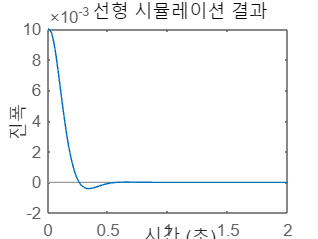

lsim(sys_cl, u, t, x0)

% 전달함수로 주어졌을 때.
clearvars;
s = tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.
모델 속성


G = 1/s^2;
sys = ss(G);
[A,B,C,D] = ssdata(sys);

% pole 선정 후 K 구하기
r1 =-1 + 1i;
r2 =-1 - 1i;
K = place(A,B,[r1 r2])

K =      2     2


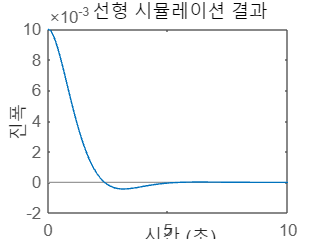

sys_cl = ss(A-B*K,B,C,D);
t = 0:0.1:10;
u = zeros(size(t));
% 여기서는 초기값을 두번째 요소로 하였는데,
% 이는 출력값 C에서 두번째 요소가 출력되도록 되어있기 때문이다.
% C = [0 1]
x0 = [0 0.01];
lsim(sys_cl,u,t,x0);